# US compatible guided Breast Biopsy Robot  

## First part - Robot dimensions

clear, clc, close all
% Most lenght and angle units are in mm and radians respectively. Otherwise
% angles are in sexagesimal degrees or meters

mainPath = getRootDirectory;

% Main robot dimensions, joint limits and other elements
L0 = 625;
L1 = 35.0;
H1 = 300.0;
L2 = 171.0;
H2 = 45.0;
H3 = 100;
L4 = 153.0;
H4 = 69.0;
L3 = H4+L4;
q_2max = 171.0;
q_4max = 113.0;
R_scannerUS = 233;
HbiopsyBed = 1100;   
numJoints = 5;

% For link 5
thicknessArmHolder = 3.18;%mm
thickessNeedleGuide = 2.29;%0.09inch
L5 = thicknessArmHolder+thickessNeedleGuide;

% Creating robotData.mat
filePath = strcat(mainPath,'\Simulink_models\Data\robotData.mat')
%save filePath L0 L1 H1 L2 H2 H3 L3 L4 H4 q_2max q_4max HbiopsyBed L5 numJoints

## Second Part - Forward Kinematics

% Defining screws axis for each robot joint
% In space coordinates or robot base in frame {s}
S1 = [0 0 1 0 0 0]';
S2 = [0 0 0 0 0 1]';
S3 = [0 -1 0 (L0+L1+L2+H2) 0 H1]';
S3_m = [0 -1 0 (L0+L1+L2+H2)/ 0 H1/1000]';
S4 = [0 0 0 1 0 0]';
S5 = S4;
Slist = [S1 S2 S3 S4 S5];

% In body coordinates or end effector in frame {e}
B5 = [0 0 0 0 0 1]';
B4 = [0 0 0 0 0 1]';
B3 = [1 0 0 0 -L3 0]';
B2 = [0 0 0 0 -1 0]';
B1 = [0 -1 0 0 H1-L3 0]';
Blist = [B1 B2 B3 B4];

% Spatial position for each joint in robot home position
r1 = [0 0 L0+L1]';
r2 = [-H1 0 L0+L1]';
r3 = [-H1 0 L0+L1+L2+H2]';
r4 = [-H1 H3 L0+L1+L2+H2]';
r5 = [-H1+L3 0 L0+L1+L2+H2]';% It is rt position. At distal part of end effector
re = [-H1+L3-L5 0 L0+L1+L2+H2]';%It is the needle base

% Home position or initial robot pose for each joint
M01 = [1 0 0 r1(1);
       0 1 0 r1(2);
       0 0 1 r1(3); 
       0 0 0 1];
M02 = [1 0 0 r2(1);
       0 1 0 r2(2);
       0 0 1 r2(3);
       0 0 0 1];
M03 = [1 0 0 r3(1);
       0 0 -1 r3(2);
       0 1 0 r3(3);
       0 0 0 1];
M04 = [0 0 1 r4(1);
       0 -1 0 r4(2);
       1 0 0 r4(3);
       0 0 0 1];
M = [0 0 1 r5(1);%Mst
     -1 0 0 r5(2);
     0 -1 0 r5(3);
     0 0 0 1];
Mst = M;
Mse = [0 0 1 re(1);
      -1 0 0 re(2);
       0 -1 0 re(3);
       0 0 0 1];

M_m = [0 0 1 r5(1)/1000;%In meters
     -1 0 0 r5(2)/1000;
     0 -1 0 r5(3)/1000;
     0 0 0 1];


## Computing Forward kinematics

% Given a joint vector of desired positions
q = [0 0 0 0];

% Computing needed input for Product of Exponentials (PoE) formula
X1 = Adjoint(TransInv(M01))*S1;
X2 = Adjoint(TransInv(M02))*S2;
X3 = Adjoint(TransInv(M03))*S3;
X4 = Adjoint(TransInv(M04))*S4;

% Relative transformation between joints
M12 = TransInv(M01)*M02;
M23 = TransInv(M02)*M03;
M34 = TransInv(M03)*M04;
M45 = TransInv(M04)*M;

% More transformation matrixes
% X12 = Adjoint(TransInv(M01))*S2;
% X23 = Adjoint(TransInv(M02))*S3;
% X34 = Adjoint(TransInv(M03))*S4;

% Method 1
% T01 = MatrixExp6s(S1,q(1))*M01;
% T12 = MatrixExp6s(X12,q(2))*M12;
% T23 = MatrixExp6s(X23,q(3))*M23;
% T34 = MatrixExp6s(X34,q(4))*M34;
% T45 = MatrixExp6s(S4,0)*M45;
% Tst = T01*T12*T23*T34*T45;

%Method 2
% T01 = M01*MatrixExp6s(X1,q(1));
% T12 = M12*MatrixExp6s(X2,q(2));
% T23 = M23*MatrixExp6s(X3,q(3));
% T34 = M34*MatrixExp6s(X4,q(4));
% T45 = M45*MatrixExp6s(X4,0);
% Tst = T01*T12*T23*T34*T45;

%Method 3
Tst = FKinSpace(q,Slist,M);% In spatial coordinates
%Tst = FKinBody(q,Blist,M);% In body coordinates


## Breast holder device

% Defining the transformation of holder's base from robot base to holder
% frame in {c} as
Tsc = [ 1 0 0 0;
        0 -1 0 0;
        0 0 -1 HbiopsyBed;
        0 0 0 1];

%Note: when the robot turns a positive degree, its body will be in the
%anterior quadrant of cartesian plane. If turns 90°, its body will will in reality -90° from x0y0z0

% Adding more date to robotData.mat
%filePath = strcat(mainPath,'\Simulink_models\Data\robotData.mat')
%save  filePath S1 S2 S3 S4 S5 Slist Blist r1 r2 r3 r4 r5 re M Mse Mst Tsc M01 Slist_m M_m '-append'

## Calculating velocities by Jacobians

q = [0.5 100 0.2 100 0];
dq = [0.1 10 0.1 10 0];
Tstt = FKinSpace(q,Slist,Mse)
Js = JacobianSpace(Slist,q)
Jb = JacobianBody(q,Slist,M)
Vs = Js*dq'
Vb = Jb*dq'

## Third Part - Basic Trayectory - Using trajectoryTest.mlx instead

%Go to \Matlab_models\Test\jointTrajectoryTest.mlx

## Inverse Kinematic using T0e

% From forward kinematics
h_s = getP(Tst);
n_s = getZ(Tst)
qq = ikRobotSIM(h_s,-n_s,'mm')

% Verifying
TT = fkRobotSIM(qq)
positionError=norm(getP(TT)-h_s);

## About Inverse kinematics

% To find q4, we need to know the robot final position and orientation. Using a
% geometic approach agorithm is posible to get q1, q2 and a3 and therefore,
% to calculate Tst([q1 q2 q3 0 0]). From here, these result and using the
% desired robot location, an algebraical approach based on Kinematic
% coupling by comparing matrixes. The result is q4 and q5.

## Optional: Using peter Corke Toolbox

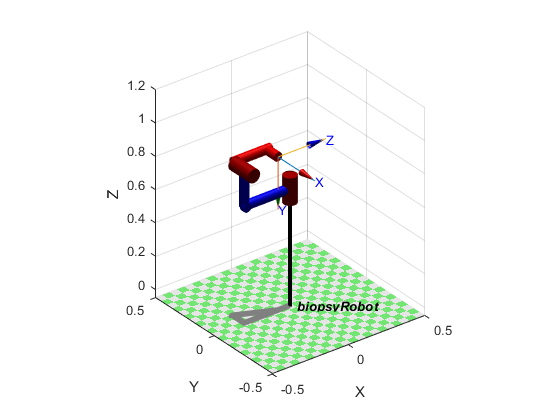

dh1 = [0 (L0+L1)/1000 0 0];
dh2 = [0 0 -H1/1000 0];
dh3 = [0 (L2+H2)/1000 0 pi/2];
dh4 = [pi/2 -H3/1000 0 pi/2];
dh5 = [pi/2 (L4+H4)/1000 H3/1000 0];
R1 = Revolute('d',dh2(2),'a',dh2(3),'alpha',dh2(4));
P1 = Prismatic('theta',dh3(1),'a',dh3(3),'alpha',dh3(4),'qlim',[0 q_2max/1000],'offset',dh3(2));
R2 = Revolute('d',dh4(2),'a',dh4(3),'alpha',dh4(4),'offset',dh4(1));
P2 = Prismatic('theta',dh5(1),'a',dh5(3),'alpha',dh5(4),'offset',dh5(2),'qlim',[0 q_4max/1000]);
robot = SerialLink([R1 P1 R2 P2],'name','biopsyRobot');
robot.base = transl(0,0,dh1(2));
% Plotting  robot home position
q = [0 0 0 0];
w = [-0.5 0.5 -0.5 0.5 -0.05 1.2];
robot.plot(q,'workspace',w);

## Robot pose in home position or Tt matrix

T = robot.fkine(q)%in meters gets better and faster results

 

T = 
         0         0         1    -0.078
        -1         0         0         0
         0        -1         0     0.876
         0         0         0         1


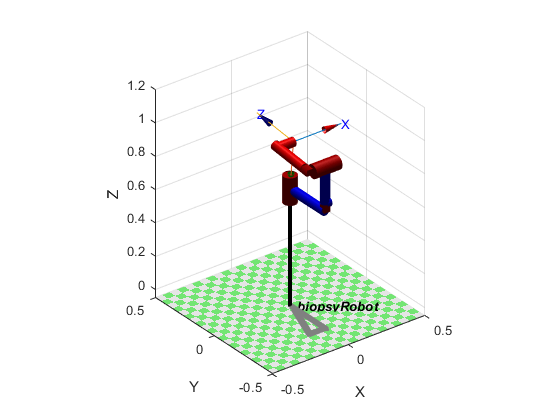

% Loading robot data
robotData = load(strcat(mainPath,'\Simulink_models\Data\robotData.mat'));

% Initial point
q0 = [0 0 0 0];
T0 = robot.fkine(q0);
T00 = fkRobotSIM([q0 0],robotData,2);
p0 = getP(T00)/1000;

% Final point
%qf = [pi/2-0.2 0.17 0.1 0.113];
qf = [pi/2 0.05 0.1 0.05];
Tf = robot.fkine(qf);
Tff = fkRobotSIM([qf 0].*[1 1000 1 1000 1],robotData,2);
pf = getP(Tff)/1000;
robot.plot(qf,'workspace',w);

[q0' qf']

ans =          0    1.5708
         0    0.0500
         0    0.1000
         0    0.0500


[p0 pf]

ans =    -0.0780   -0.0000
         0   -0.0294
    0.8760    0.9532


ikRobotSIM(pf*1000,getZ(Tff),'m',robotData)

ans =     1.5708
    0.0500
    0.1000
    0.0500
         0


numPoints = 10;
s =  linspace(0,1,numPoints);
s = repmat(s,4,1);
deltaQ = q0' + qf'.*s

deltaQ =          0    0.1745    0.3491    0.5236    0.6981    0.8727    1.0472    1.2217    1.3963    1.5708
         0    0.0056    0.0111    0.0167    0.0222    0.0278    0.0333    0.0389    0.0444    0.0500
         0    0.0111    0.0222    0.0333    0.0444    0.0556    0.0667    0.0778    0.0889    0.1000
         0    0.0056    0.0111    0.0167    0.0222    0.0278    0.0333    0.0389    0.0444    0.0500


deltaT = zeros(4,4,numPoints);
for i=1:numPoints
    deltaT(:,:,i) = fkRobotSIM([deltaQ(:,i)' 0].*[1 1000 1 1000 1],robotData,2);
end
deltaP = zeros(3,numPoints);
for i=1:numPoints
    deltaP(:,i) = getP(deltaT(:,:,i));
end
deltaP = deltaP/1000;%in m

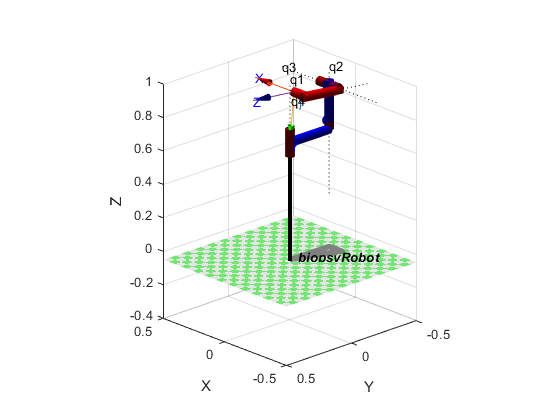

% By default toolbox
% plot3(deltaP(1,:),deltaP(2,:),deltaP(3,:),'Color',[0 1 0],'LineWidth',2);
% xlim([-0.5 0.5]);
% ylim([-0.5 0.5]);
% zlim([-0.05 1.2]);
% hold on;

plot2(deltaP')%Using RTB toolbox
hold on;
robot.plot(deltaQ','scale',1,'perspective','jointdiam',1,'jaxes','shadow','workspace',w); % hareketli
view([226.67 21.09]);

### A quick test for robot trajectory

% *** Uncomment ***
%t = [0:0.05:3];
% Jtraj usues a quintic interpolation
%[Q,QD,QDD] = JTRAJ(Q0, QF, M, QD0, QDF) as above but also specifies
%initial QD0 (1 × N) and final QDF (1 × N) joint velocity for the trajectory.
%[Q,QD,QDD] = JTRAJ(Q0, QF, T) as above but the number of steps in the
%trajectory is defined by the length of the time vector T (M × 1).
%qq = jtraj(q0,qf,10)'

## Robot trajectory

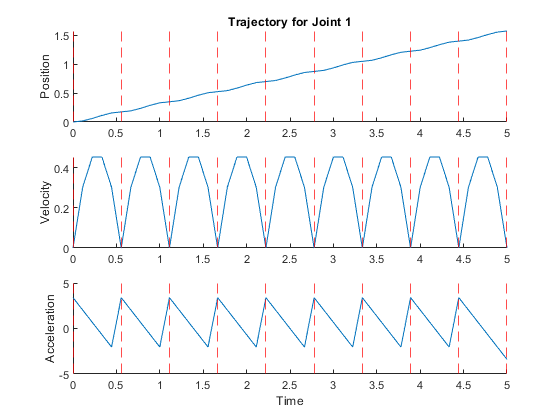

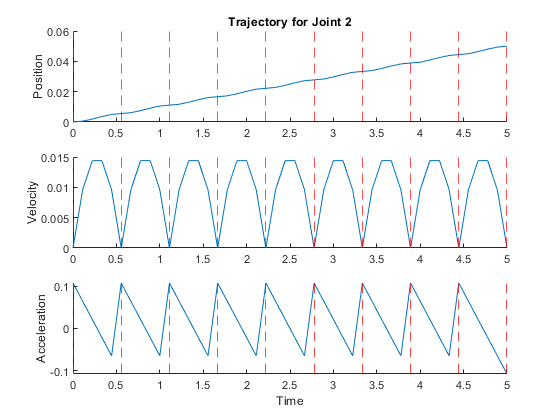

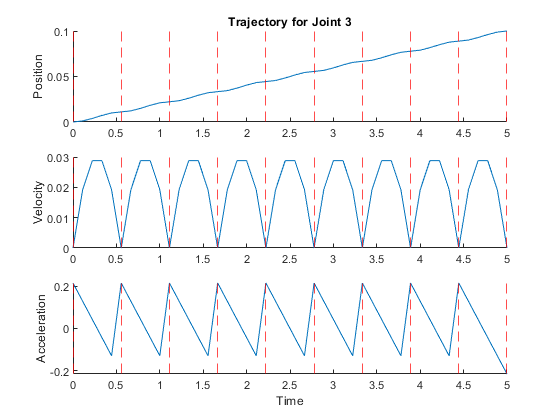

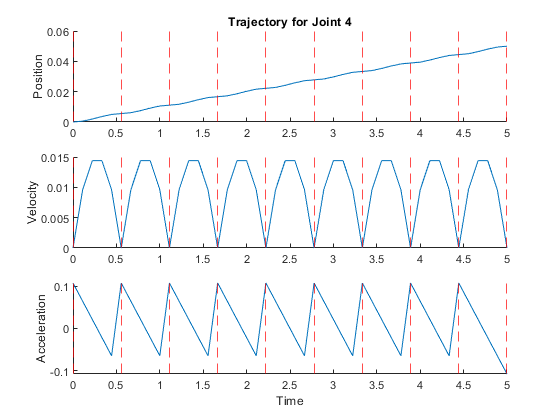

%Initial settings
t0 = 0;
tf = 5;
twp = (tf-t0)/(numPoints-1);
timePoints = t0:twp:tf;
ts = twp/5;
t = 0:ts:5;

% The total time discretization can be calculated as: ts*(numberPoints-1)+1
% Using in radians and meters
[qq, dqq, ddqq] = cubicpolytraj(deltaQ, timePoints, t);
plotTrajectory(t,qq,dqq,ddqq,'Names',"Joint " + string(1:numJoints),'WaypointTimes',timePoints)

% Calculting 
numInterPoints = length(qq);
nP = zeros(3,numInterPoints);
nZ = nP;
for i=1:numInterPoints
    T = fkRobotSIM([qq(:,i);0],robotData,2);
    nP(:,i) = getP(T);
    nZ(:,i) = getZ(T);
end

% For testing with jointTrajectoryTesy.m
savePath = strcat(mainPath,'\Matlab_models\Data\newTrajectory.mat');
save(savePath,'qq','dqq','ddqq','ts','twp','numPoints','deltaP',"deltaQ","deltaT",'timePoints','t');